### **SW and Methods for Statistical Analysis**

# **Time Series Analysis of Nvidia Stock Prices (2012-2024) - **

# **The Univariate Case**

In this MATLAB Livebook, a comprehensive Univariate Time Series Analysis will be carried out to study the stock prices and returns of the most capitalized (as of June 24th) company of the world, Nvidia Corporation (**NASDAQ: NVDA**).

This livebook, the data and supplemental materials will be available on this [Github Repository](https://github.com/trarez/EsameSoftware).

The livebook will mainly have a mix of programming, statistical and financial notions. Technical and non-intuitive aspects of the scripts will be explained in the cells with "%%".

*Where do I gather information for this project? *Main Resources:

- [Analysis of Financial Time Series](https://www.wiley.com/en-ca/Analysis+of+Financial+Time+Series%2C+3rd+Edition-p-9780470414354) by Ruey S. Tsay;

- [Time Series Analysis with Applications in R](https://link.springer.com/book/10.1007/978-0-387-75959-3) by Jonathan D. Cryer and Kung-Sik Chan;

- [Forecasting: Principles and Practices](https://otexts.com/fpp3/) by Rob J. Hyndman and George Athanasopoulos;

- Professor's slides;

- MATLAB Tutorials;

- Investopedia;

- Youtube Tutorials: [Economic Time Series Modelling in MATLAB](https://www.youtube.com/watch?v=UCChM5Mul_E), ;

- English Wikipedia (with a grain of salt);

- ... and a bit of Gemini LLM (with two grains of salt!).

### Data Importing and Descriptive Statistics

The data have been downloaded at June 24th on Yahoo! Finance and imported on Github for easier accessibility.

df = readtable("https://raw.githubusercontent.com/trarez/EsameSoftware/main/Nvidia%20Stock%20Prices.csv","VariableNamingRule","preserve")

df = 2915×7 table
       Date        Open       High        Low       Close     Adj Close      Volume  
    __________    _______    _______    _______    _______    _________    __________

    2012-11-20     0.2895    0.29075    0.28425    0.28725     0.26517     3.3698e+08
    2012-11-21    0.28725    0.29625      0.287     0.2955     0.27279     4.2231e+08
    2012-11-23    0.29675      0.301    0.29525     0.2975     0.27464     2.7693e+08
    2012-11-26      0.298     0.3035     0.2975    0.30275     0.27948      3.646e+08
    2012-11-27     0.3015     0.3085      0.299      0.304     0.28064      4.514e+08
    2012-11-28    0.30275      0.308      0.299     0.3065     0.28294     3.9833e+08
    2012-11-29      0.307     0.3085        0.3      0.

rng(0, "twister") % for eventual reproducibility

During a trading day, the stock prices vary. Yahoo! Finance provide basic intra-day distributional values. With these it might be possible to deepen the analysis (for example, by building *candlesticks *on a time series*, *figure below), but for now let's just consider **adjusted close** prices.

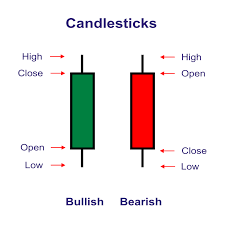

The closing price is the raw price, which is just the cash value of the last transacted price before the market closes. The adjusted closing price factors in anything that might affect the stock price after the market closes, for example dividend payments to shareholders, as shown in the formula below (Source:[ *Investopedia*](https://www.investopedia.com/terms/a/adjusted_closing_price.asp)*). *


$$R_t = \frac{P_t + D_t}{P_{t-1}} - 1$$


df = df(:, {'Date', 'Adj Close'});
dates = df.Date;
prices = df.("Adj Close");

It's important to keep in mind that trading days differ from actual days, because during the weekend and holidays the stock market is closed.

There are some strategies to deal with this:

- Leave the data as they are: technically no information is lost, because no trading occurs

- Missing Data Imputation

- ...

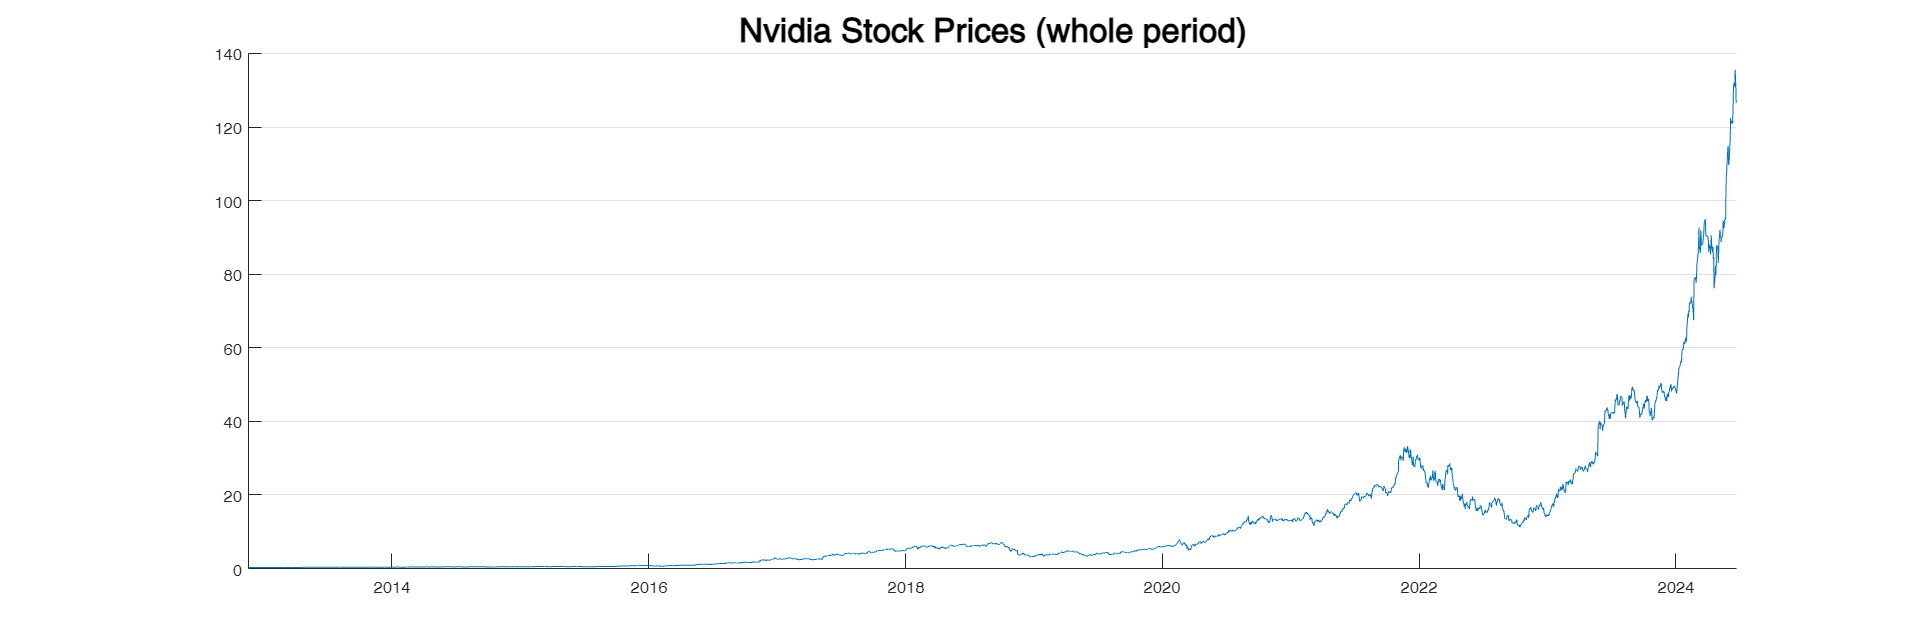

figure();
plot(dates, prices);
title("Nvidia Stock Prices (whole period)", "FontSize",20);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 1800, 600]);
box off

The time series is splitted in half and the visualization is performed on two different plots, in order to better understand the price levels before January 2016.

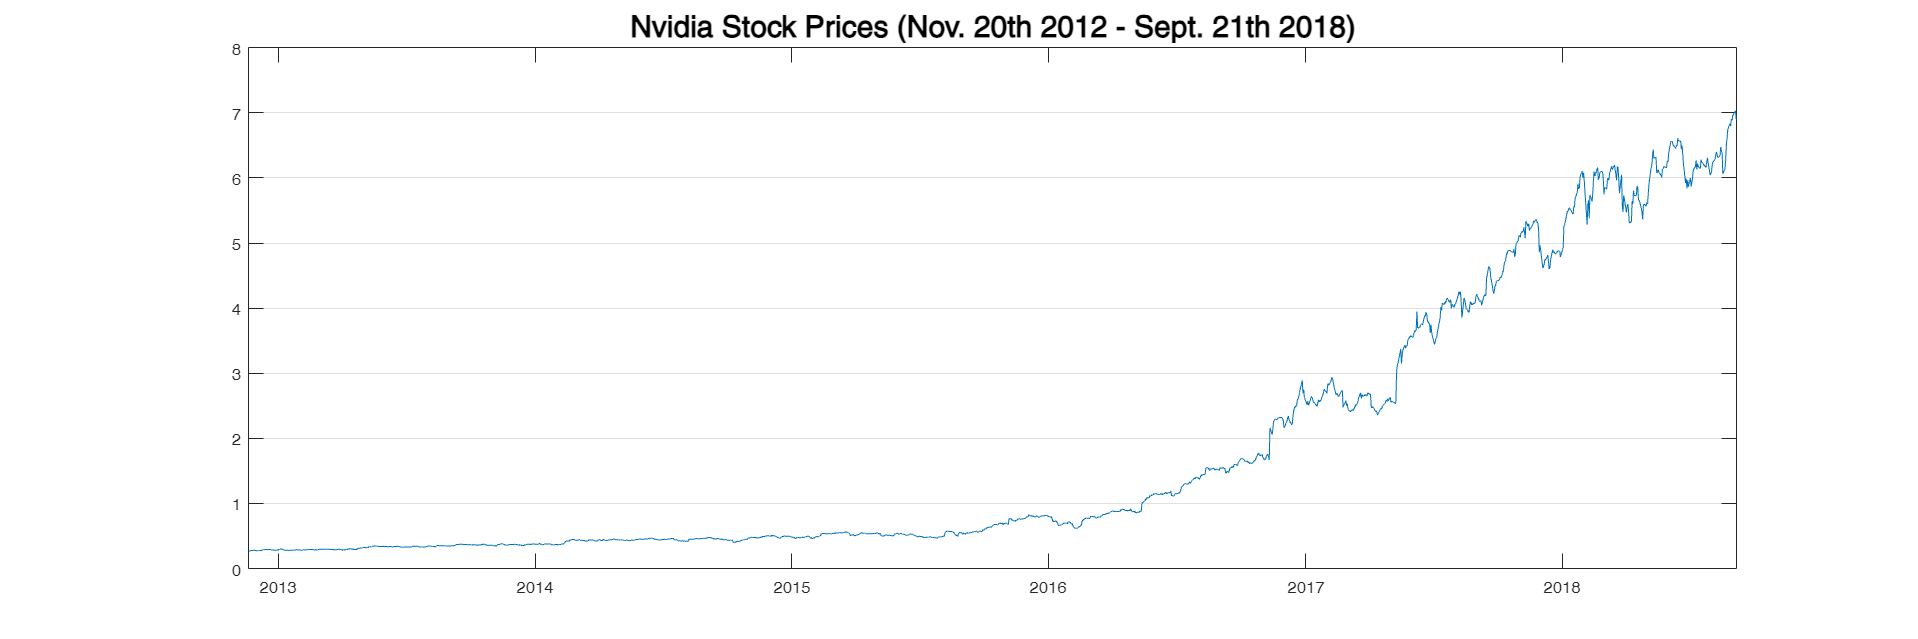

middleDay = round(length(prices)/2);
plot(dates(1:middleDay) , prices(1:middleDay));
title("Nvidia Stock Prices (Nov. 20th 2012 - Sept. 21th 2018)", "FontSize", 18);
set(gca, "XGrid", "off", "YGrid", "on");

set(gcf, 'position', [10, 10, 1800, 600]);

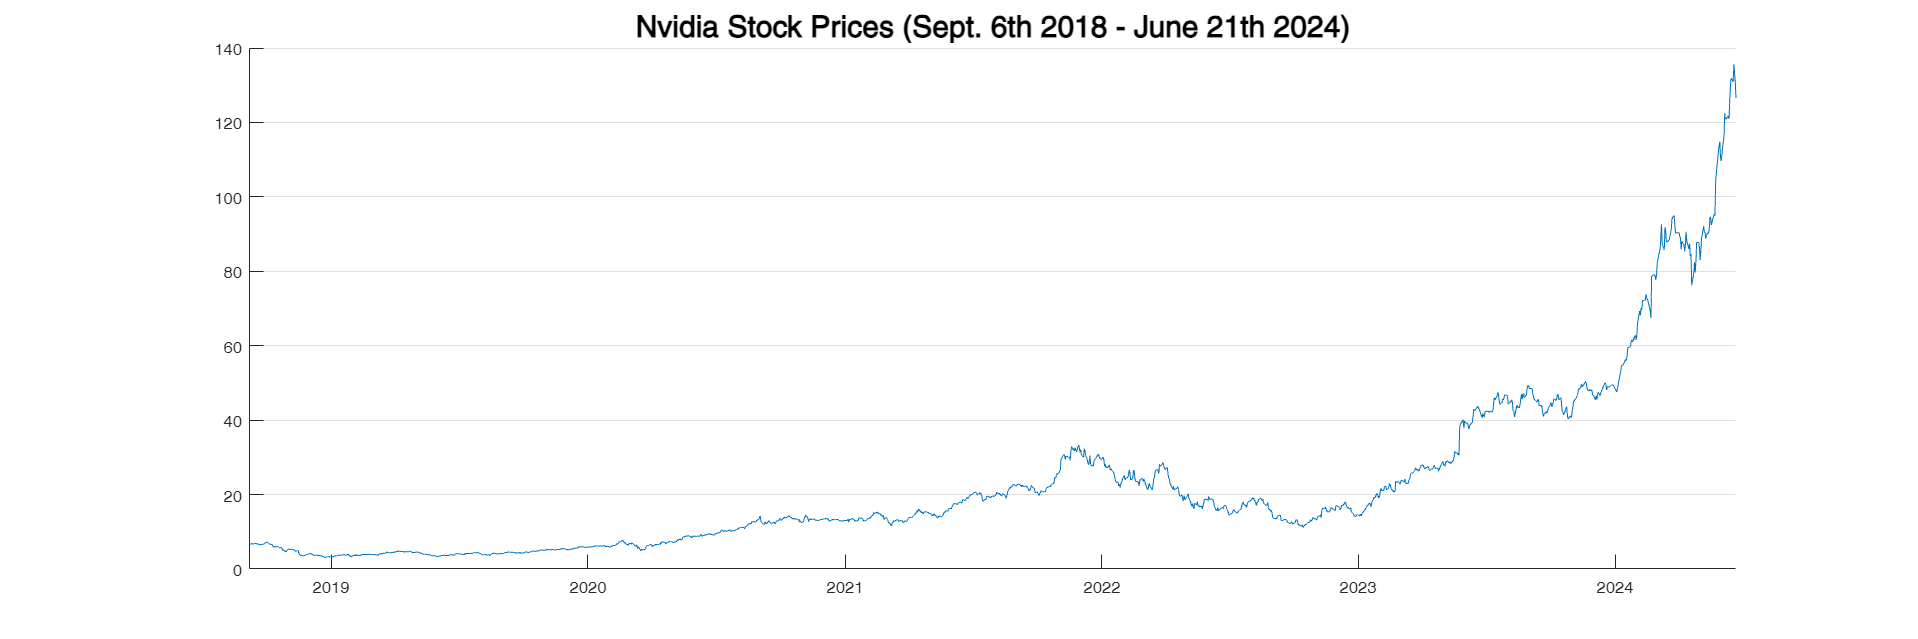

middleDayNext = round(length(prices)/2) + 1;
plot(dates(middleDayNext:end) , prices(middleDayNext:end));
title("Nvidia Stock Prices (Sept. 6th 2018 - June 21th 2024)", "FontSize", 18);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 1800, 600]);
box off

Given the quasi-exponential nature of the time series (especially in the second half), the series can be plotted in a logarithmic scale.

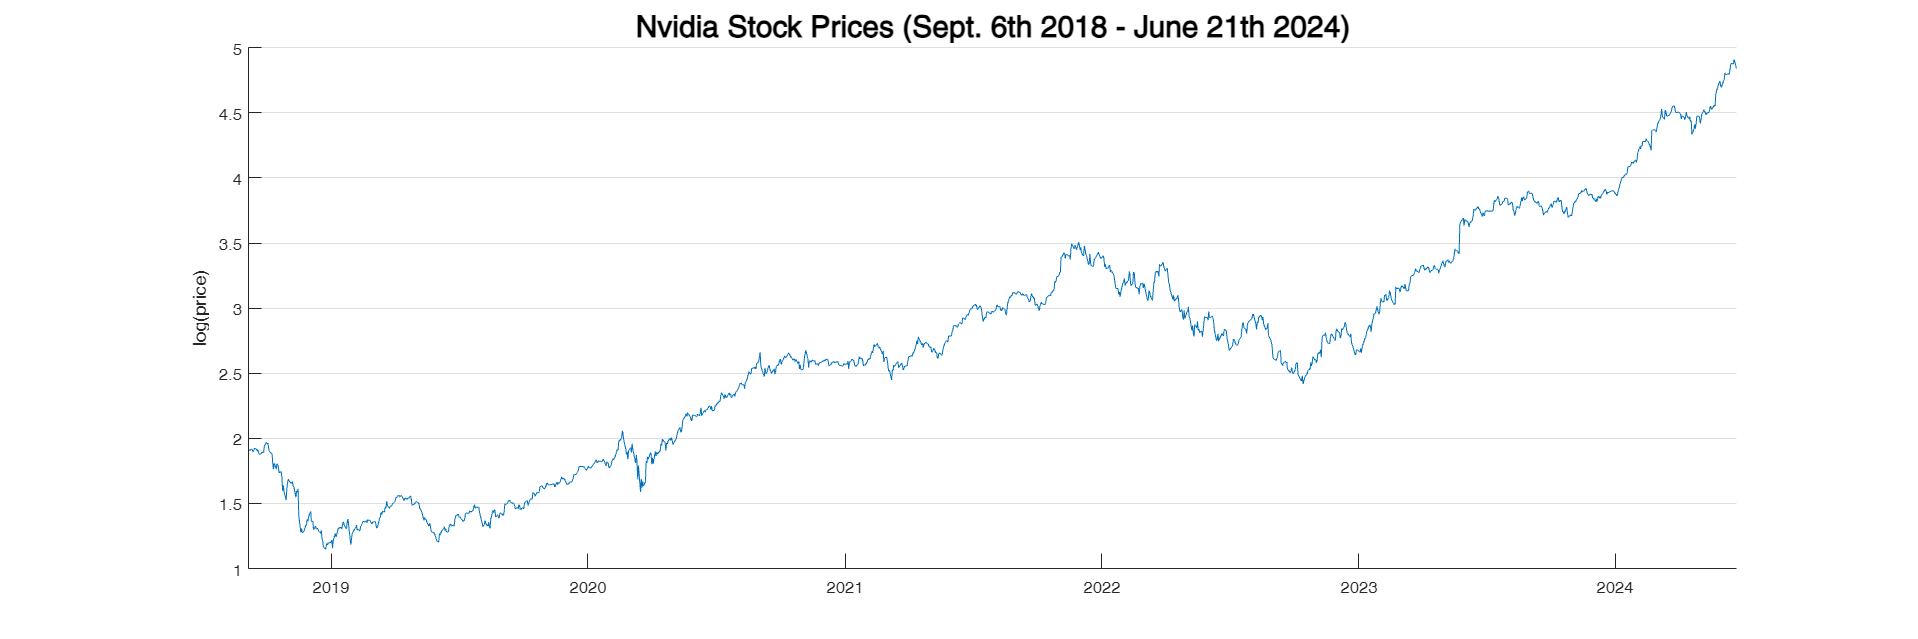

plot(dates(middleDayNext:end) , log(prices(middleDayNext:end)));
title("Nvidia Stock Prices (Sept. 6th 2018 - June 21th 2024)", "FontSize", 18);
set(gca, "XGrid", "off", "YGrid", "on");
ylabel("log(price)");
set(gcf, 'position', [10, 10, 1800, 600]);
box off

What interests the most to analysts and investors are not prices per se, but the stock **returns **(daily, monthly, yearly, ...).

Campbell, Lo and MacKinlay (1997) give two main reasons for using returns:

- for average investors, return of an asset is a complete and scale-free summary of the investment opportunity; 

- return series are easier to handle than price series because the former have more attractive statistical properties.

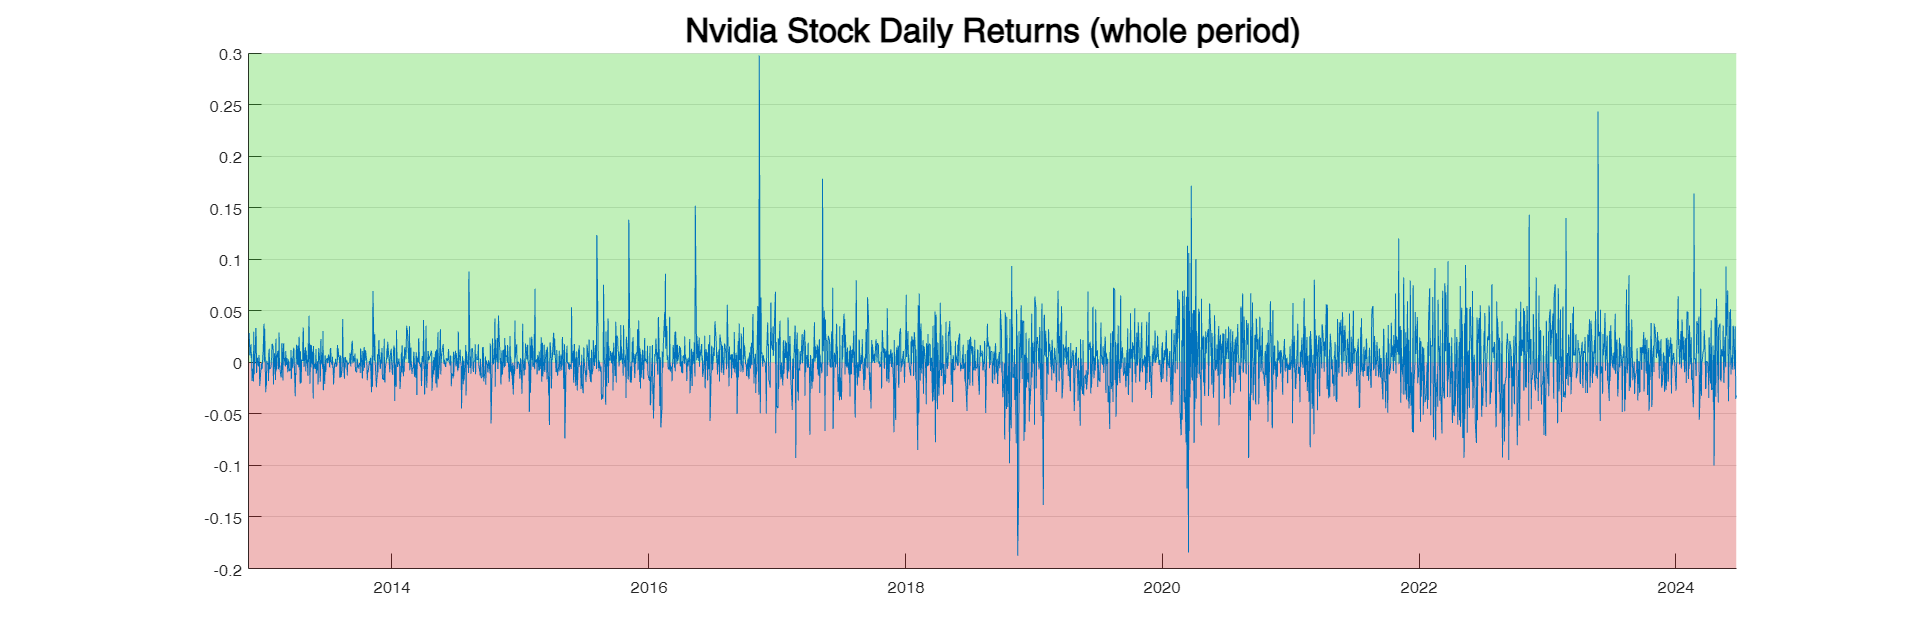

returns = tick2ret(prices); % function that converts price levels to return. Differencing causes the first observation to be lost.
figure();
hold on;
patch([dates(1), dates(end), dates(end), dates(1)], [0.3, 0.3, 0, 0], [0.2, 0.8, 0.1], "FaceAlpha", 0.3, "EdgeColor", "none")
patch([dates(1), dates(end), dates(end), dates(1)], [0, 0, -0.2, -0.2], [0.8, 0.1, 0.1], "FaceAlpha", 0.3, "EdgeColor", "none")
plot(dates(2:end), returns)
title("Nvidia Stock Daily Returns (whole period)", "FontSize",20);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 1800, 600]);
hold off;

This is the main time series of interest and inquiry. From here we can understand an essential phenomenon of financial markets, **volatility**, a process concerned with the evolution of conditional variance of the return over time. Interesting periods of volatility may be highlighted to analyze the phenomenon with proper models (GARCH and its broad range of extensions, Implied Volatility Estimation and so forth). More of that later in the Volatility Analysis section.

A common feature of most asset daily returns distributions is their ***fat-tailedness. ***This *fat-tailedness, *quantified by (excess) **kurtosis **(the 4th distribution moment), means there is a higher probability of extreme events (returns much higher or lower than the average value) that fall outside 2-3 standard deviations (2-3σ) from the mean with respect to the normal distribution. This is one of the reason why assuming the normal distribution for returns is limited. Another reason is due to the **skewness **(3rd moment), where the distribution is not symmetrical around the mean.

Given a sufficient number of observations, it is possible to build the empirical distribution curve with both **Kernel Density Smoothing **and **histograms**. Both the KDE (continuous) and histogram (discrete) are *non-parametric *estimations of the theoretical PDF.

## AGGIUSTARE, NORMALIZZARE I VALORI

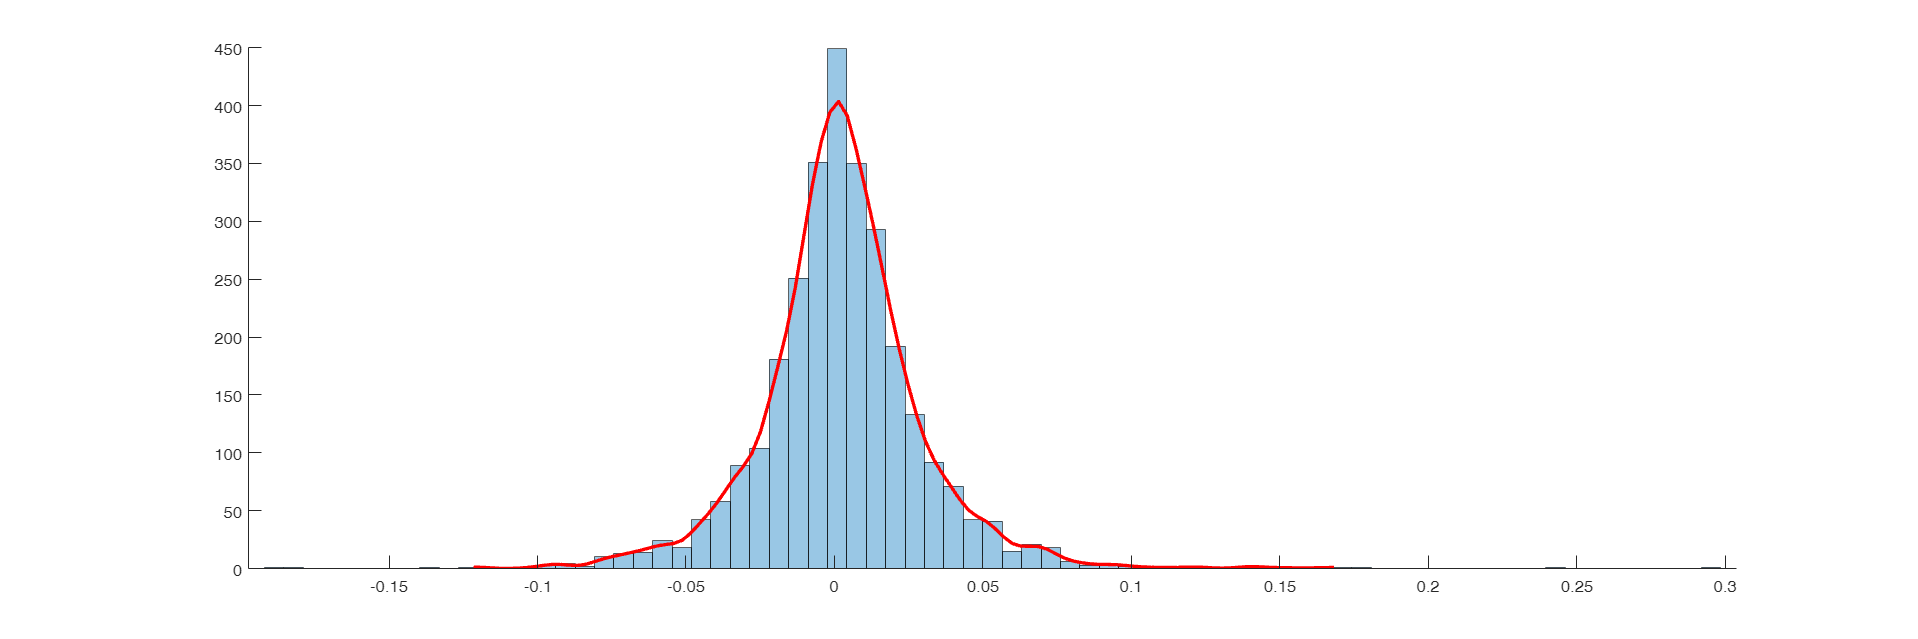

h = histfit(returns, 75, "kernel");

%% The "histfit" function belongs to the Statistics and Machine Learning Toolbox. It permits to simultaneously create a histogram and fit a kde, if specified. 
%% Distributions may be fitted (parametric).

%% histfit outputs a composite object, made of the kde curve and the histogram. These are called handles.
h(1).FaceAlpha = 0.4; h(1).EdgeAlpha = 0.6; %% Handle for histogram
h(2).Color = "Red";
box off

At first glance, the KDE recalls a *leptokurtic normal distribution.*

Another common graphical method is the **Q-Q plot**, as it compares the sample quantiles to a specific distribution quantiles. It can also be used to compare two samples, to see whether they come from the same distribution (same hypothesis of the *two-sample Kolmogorov-Smirnov, *even though this one is a formal statistical test with its specific test statistic).

For now let's use it to compare our sample with the normal distribution:

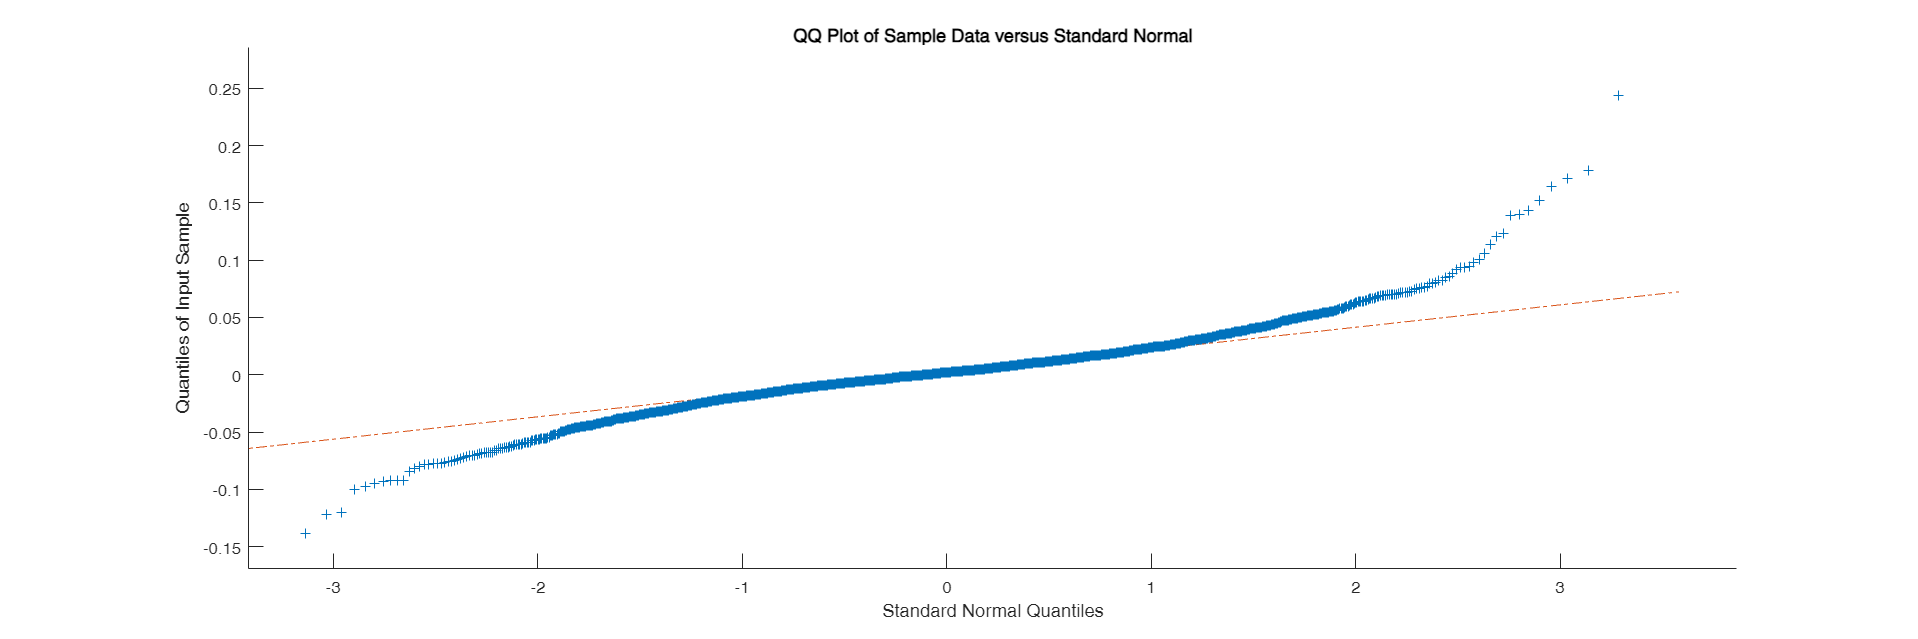

qqplot(returns) %% the default hypothesized distribution is the normal one. Others can be considered.

The S-shaped data means the sample have "more extreme values" than the normal distribution.

**Extreme Value Theory **is an important field of quantitative finance, especially for *risk management *(hedging strategies).

### Before going further: *gross *or *log-returns?*

The first important analyst decision (*forking path*) when it comes to analyzing financial data is to choose between *gross *or *log returns*.

Gross returns are [complete].

Log returns, instead, have more tractable statistical and mathematical properties. These are preferred for financial time series analysis, especially because the sample may more probably resemble a normal distribution (absolute higher values tend to be shrunk the most, less *fat-tailedness*) with a stable variance.

The logarithmic function is a monotonic transformation, hence only values magnitude change a bit, as shown below:

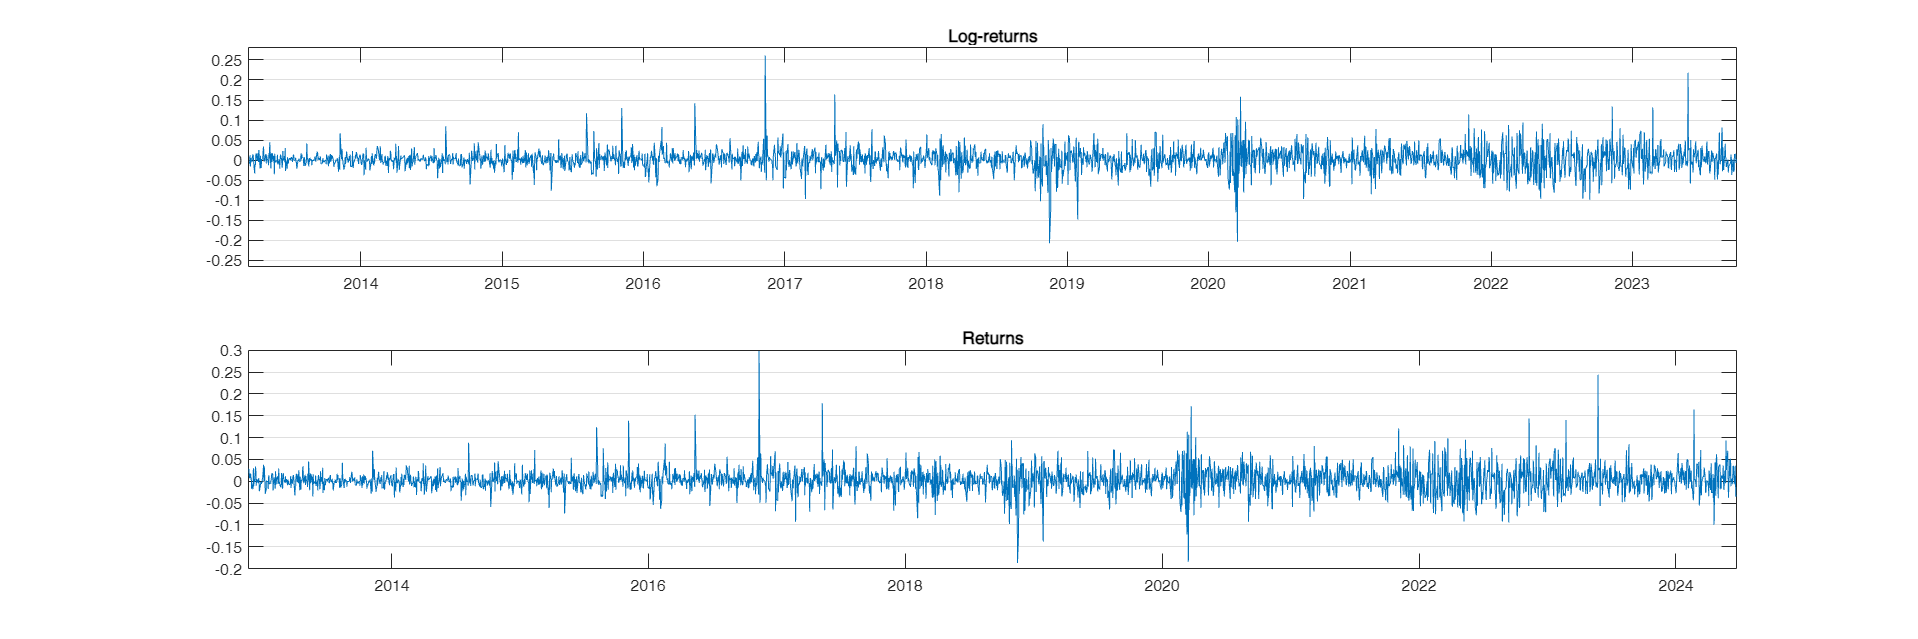

logreturns = log(1 + returns);
subplot(2,1,1);
plot(dates(2:end), logreturns);
set(gca, "XGrid", "off", "YGrid", "on");
title("Log-returns")

subplot(2,1,2);
plot(dates(2:end), returns);
set(gca, "XGrid", "off", "YGrid", "on");
title("Returns")

For a better tractation on log transformations in economic and financial time series, read [*The Role of the Log Transformation in Forecasting Economic Variables*](https://papers.ssrn.com/sol3/papers.cfm?abstract_id=1368131) by *Helmut Lütkepohl* and *Fang Xu.*

*TL:DR: "For a range of economic variables substantial forecasting improvements from taking logs are found if the log transformation actually stabilizes the variance of the underlying series. Using logs can be*

*damaging for the forecast precision if a stable variance is not achieved."*

% hold on
% patch([dates(2000), dates(2400), dates(2400), dates(2000)], [0.3, 0.3, -0.2, -0.2], [0.2, 0.8, 0.1], "FaceAlpha", 0.4, "EdgeColor", "none")
% plot(dates(2:end), returns, Color=[0.44, 0.23, 0.77]);
% title("Nvidia Returns (whole period)", "FontSize",20);
% set(gca, "XGrid", "off", "YGrid", "on");
% set(gcf, 'position', [10, 10, 1800, 600]); %

### Model Building Strategy

*Time Series Analysis; Forecasting and Control *by Box-Jenkins (1970) may be considered as The Bible of time series forecasting.

They proposed an *iterative three-stage modeling approach, *detailed below:

- **Model identification and selection**

- **Parameter estimation **(model fitting)

- **Statistical Model Checking **(diagnostics)